# Quickstart Guide: Visualization

soma = ELFENN.Section('soma', 'radius', 15,...
    'sectionLength', 30, 'nSeg', 1, 'sectionGeometry', 'S');
axon = ELFENN.Section('axon', 'radius', 2.5, ...
    'sectionLength', 500, 'nSeg', 5);

cell = ELFENN.Cell('cell1');
cell.connectsection(soma, axon, [0,0,0]); 

network = ELFENN.Network();
network.addcell(cell, [0,0,0]);
cell.name = 'cell2';
network.addcell(cell, [500,20, 5]);
network.complete();
network.setdynamics(ELFENN.Mechanisms.Cellular.HH.default_parameters())
endix = network.cells(1).sections(2).segments(end).connectivityid;
synapse_params = ELFENN.Mechanisms.Synapse.Alpha.default_parameters;
synapse_params.tau = 0.1;
synapse_params.gSyn = 5; % uS

network.addchemicalsynapse(network.getcellbyname('cell2').soma,...
    endix, @ELFENN.Mechanisms.Synapse.Alpha.s, ...
    synapse_params, 'unscaled');
injectedParameters.amp = 1; % nA
network.addintracellularelectrode(network.getcellbyname('cell1').soma,...
    @ELFENN.Mechanisms.Stimulus.dc_stimulus, injectedParameters, 'unscaled')
IC = [-64.974597972708651 0.053091060286233, ...
    0.594063768482307 0.318032413734906];
conductivity = 0.05;
solver = ELFENN.Supervisor(@ELFENN.Mechanisms.Cellular.HH.ode,...
    network, IC, conductivity);
solver.ephapticStatus = 'on';
solver.transientLength = 0;
solver.tmax = 100;
[t,y] = solver.run();
network.assignsolutionindex("Vm", "m", "h", "n");

## Visualizing Geometry

Geometries can be visualized at any level: from Sections to Networks with the *plot** functions

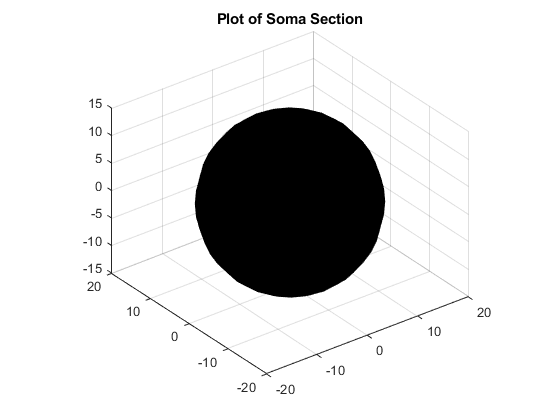

figure
plotsection(soma);
title('Plot of Soma Section')

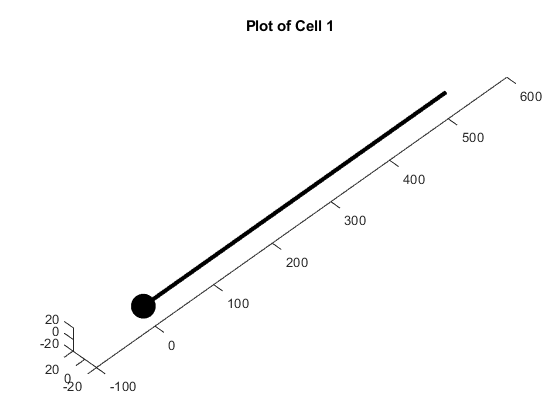


figure
plotcell(cell);
title('Plot of Cell 1')
view([-45, 45])

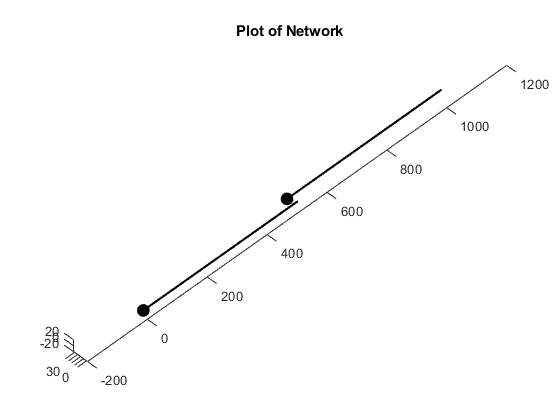


figure;
plotnetwork(network);
title('Plot of Network')
view([-45, 45])

For simplicity if you would like a "line-drawing" of the plots, you can do the following where cylinders are approximated by line segments so you get "prettyness" at the expense of radius

figure
plotsection(soma, 'style', 'line');
title('Plot of Soma Section')

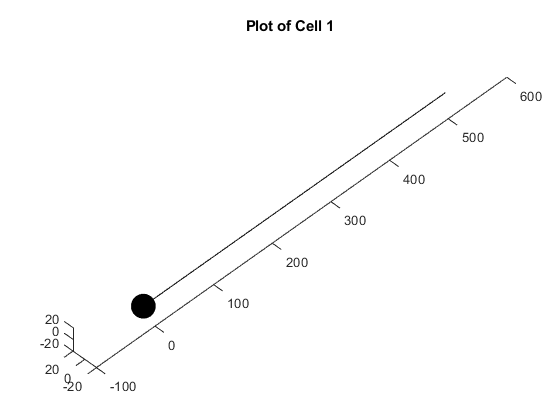


figure
plotcell(cell, 'style', 'line');
title('Plot of Cell 1')
view([-45, 45])

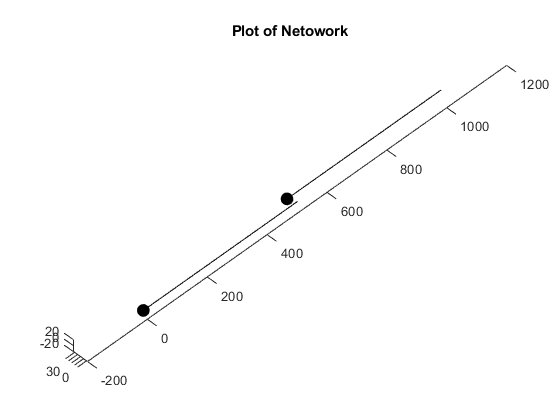


figure;
plotnetwork(network, 'style', 'line');
title('Plot of Netowork')
view([-45, 45])

The last thing we will show is how to set the color of geometries - to highlight them for example.

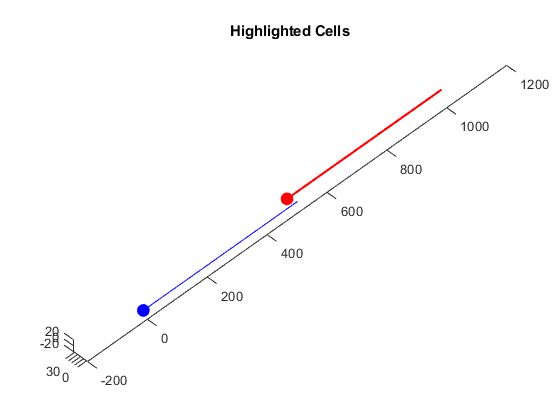

figure
plotcell(network.cells(1), 'style', 'line', 'color', 'b');
plotcell(network.cells(2),'color', 'r');
title('Highlighted Cells')
view([-45, 45])

## Visualizing Results

Assides from extracting traces and plotting them normally. There are 2 main types of plots one would want to generate.

- LFPs

- A variable on the neuron geometry

Currently the LFP plotting features can only plot LFPs on a plane, and in order to take advantage of the built in generators, the plane needs to be aligned with the coordinate axes (X-Y, Z-Y, ...).

The first thing we need to do is to reconstruct the membrane current. We use time step 430 because it's a point that looks neat but you could just as easily pick it based on time (ie. t = 5ms)

Im = solver.reconstruct_I_trans(t, y); 
time_index = 640;
Im = Im(time_index, :);


Next we can compute the LFP

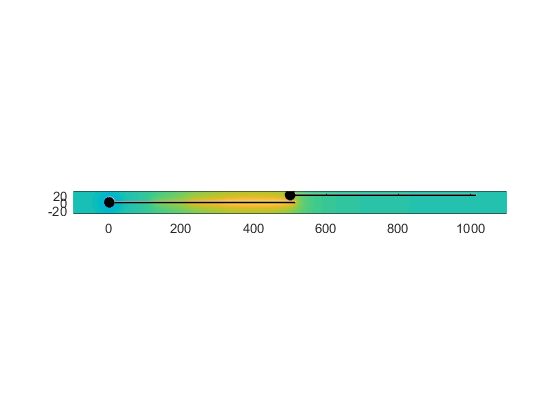

figure;
x_bounds = [-100, 1100];
x_res = 2;
y_bounds = [-30, 30];
y_res = 2;
z_bounds = [2.5, 2.5];
z_res = 1;

[x_electrode, y_electrode, z_electrode] = generate_electrode_grid(x_bounds, x_res, y_bounds, y_res, z_bounds, z_res);
LFP = get_lfp_snapshot(network, Im, x_electrode, y_electrode, z_electrode, conductivity);


plotLFP(network, LFP, x_electrode, y_electrode, z_bounds(1),1)
caxis([-0.06, 0.06])
plotnetwork(network);

The flag at the end of the plotLFP means to whether or not to mask the geometry - i.e. whether or not to remove points evaluated within the geometry. The mask is not visible as we've overlayed the geometry.

Removing the geometry shows

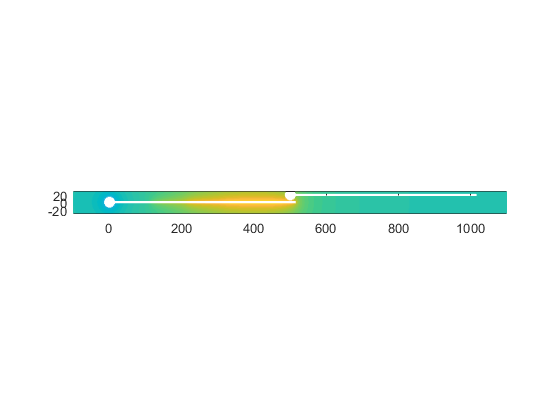

figure;
plotLFP(network, LFP, x_electrode, y_electrode, z_bounds(1),1)
daspect([1,1,1])
caxis([-0.06, 0.06])

It is not necissary to mask the geometry (specified by a 0) however the potential may be evaluated inside the cell - skewing the voltage range.

We can also overlay dynamical variables overtop the geometry

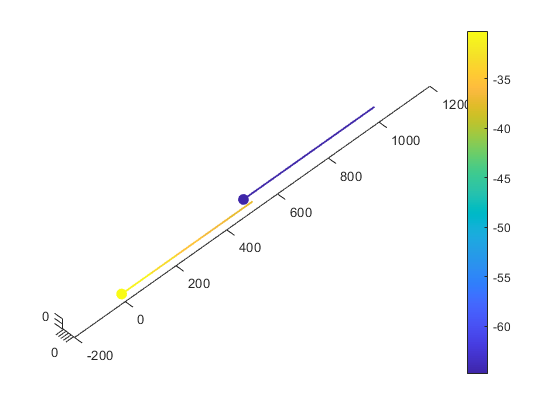

figure;
color_set = @parula; % or whichever colormap you prefer
plot_dynamics_on_neuron(network,y, 'Vm', time_index, color_set)
view(-45, 45)